% SET OPTIONS
importLogs = true;
rtRounding = 10;

%File directories
%Traj-0004:
imgFolder = fullfile('.', '/QuadSimEnv/Results/Traj-0005/Few');
logFile = fullfile('.','/QuadSimEnv/Results/Traj-0005/simout.mat');

% INITIALISE CONSTANTS

%INITIALISE WORLD MAP
map = load('./Resources/map.mat');

%Camera variables
%K = [1274.58238813250 0 627.693937913345; 0 1273.36371905619 405.441250468717; 0 0 1]; %23 mm calibration
%K=   [605.8071 0 316.6903; 0 608.4646 256.6409; 0 0 1.0000]; %31 mm calib
K = [1107 0 960; 0 1107 540; 0 0 1]; %virtual camera

%Checkerboard variables
X_pnts_W = map.worldObjectStruct.checkers.Corners;
checkerSize = map.worldObjectStruct.checkers.NumSquares;
checkerEdgeLength = map.worldObjectStruct.checkers.SquareSize; %mm
checker_w_mm = 31*checkerSize(2);
checker_h_mm = 31*checkerSize(1);

%Known coordinate transformations (mapping)
R_unreal2World = [1 0 0; 0 1 0; 0 0 1];

%other variables
p3pResult = struct();
inlierThreshold = 0.5;


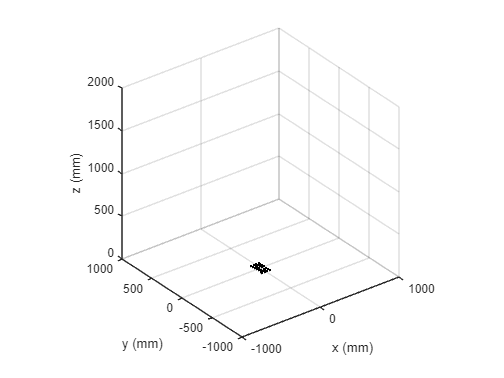

%INTIALISE PLOT
close all

%ADD TRAJECTORIES
plotStruct = initPlots('KneipN', 'Matlab', 'Verification');
p3pPlotting.addCheckerboard(plotStruct.traj.Ax, X_pnts_W);

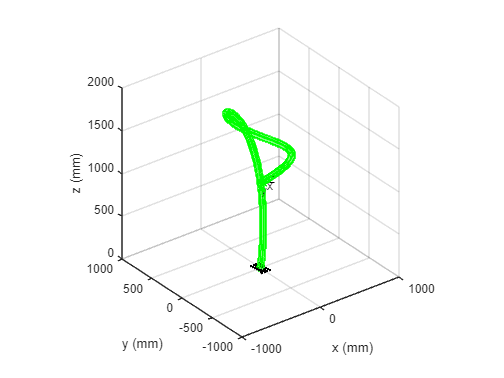

%IMPORT & PLOT LOGGED DATA
if importLogs ==true
    [cam_rtHist_GT, cam_timeHist_GT, cam_stateHist_GT] = imgFuncs.importSimLog(logFile,  R_unreal2World);
    lineObj_Ver = plotStruct.traj.plotLines.Verification.line;
    axTextArr_Ver=plotStruct.traj.plotLines.Verification.frameText;
    axLineArr_Ver = plotStruct.traj.plotLines.Verification.frameLines;
    p3pPlotting.updateTraj(lineObj_Ver, axTextArr_Ver, axLineArr_Ver, cam_rtHist_GT);
end

%IMPORT IMAGES
[I_seq, I_seq_times] = imgFuncs.importImageSeq(imgFolder);

Working on frame 1
Working on frame 2
Working on frame 3
Working on frame 4
Working on frame 5
Working on frame 6
Working on frame 7
Working on frame 8
Working on frame 9
Working on frame 10
Working on frame 11
Working on frame 12
Working on frame 13
Working on frame 14


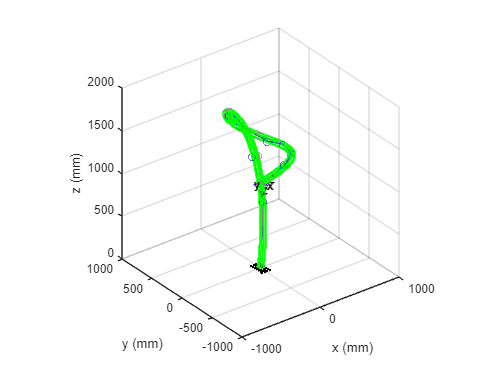

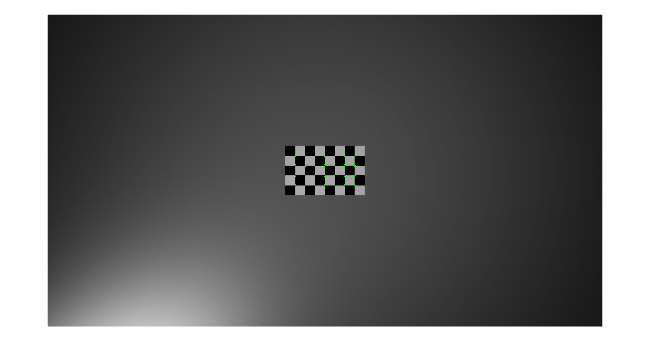

%RUN AND PLOT P3P FOR EACH CHECKERBOARD IMAGE
goodFrameCounter = 0;
for i=1:size(I_seq,3)

    disp(strcat("Working on frame ", string(i)));
    
    %Get current frame
    I=I_seq(:,:,i);
    imageArrSize = size(I);
    imageSize=imageArrSize(1:2);

    %Find checkerboard corners
    [x_pnts_i, checkerSize_detected] = detectCheckerboardPoints(I);
    x_pnts_i = transpose(x_pnts_i);    

    %discard any frames where too few corners have been detected
    if (checkerSize_detected(1) ~= checkerSize(1)) || (checkerSize_detected(2) ~= checkerSize(2))
        disp(strcat("Discarding frame ", string(i)));
        continue
    end

    %Otherwise, continue:
    goodFrameCounter = goodFrameCounter +1;
    %Extract useful information
    time_I = I_seq_times(:,i); %time associated with frame
    [~,closestIndex] = min(abs(cam_timeHist_GT-time_I));
    Rt_log_i = cam_rtHist_GT(:,:,closestIndex);


    %Run P3P
    p3pResult = runP3P(p3pResult, time_I, x_pnts_i, X_pnts_W, K, imageSize, checkerSize, inlierThreshold, rtRounding,  'KneipN', 'Matlab');
    plotStruct.traj = updatePlot(plotStruct.traj, p3pResult);


    %Calculate error
    if importLogs == true
        p3pResult = calcRtError(p3pResult, cam_rtHist_GT, cam_timeHist_GT);    
    end

    %Display checkerboard image for this iteration - for troubleshooting
    if (checkerSize_detected(1) <= checkerSize(1)) || (checkerSize_detected(2) <= checkerSize(1)) 
        if i==1
            checkerFig = figure();
            checkerAx = axes('Parent', checkerFig);
            checkerImg = imshow(imgFuncs.markDetectedCheckers(I, x_pnts_i), 'Parent', checkerAx);
        else
            checkerImg.CData = (imgFuncs.markDetectedCheckers(I, x_pnts_i));
            drawnow;
        end 
    end

 end

 
 save(fullfile('.', '/Results/', "p3pResult"));
 



% %run state estimator
% 
% %options
% p3pData = p3pResult.KneipN;
% timesToRun = p3pData.time;
% timesToRun = [0, timesToRun]; %append start time
% 
% %Initialise state and estimator variables
% %Get initial state from verification data
% x_k = cam_stateHist_GT(:,1);
% %Strip out 3D variables (only considering 2D quad for now)
% x_k(1,2) = [];
% x_k(1,3) = [];
% x_k(1,3) = [];
% 
% 
% 
% 
% %At each time step
% %Which time steps?
% for i=1:size(timesToRun+1)
% 
%     [x_k, P_k] = EKF_2dQuad_funcs.EKF_loop(x_k, P_k, u_k, Q, z_k, W)
